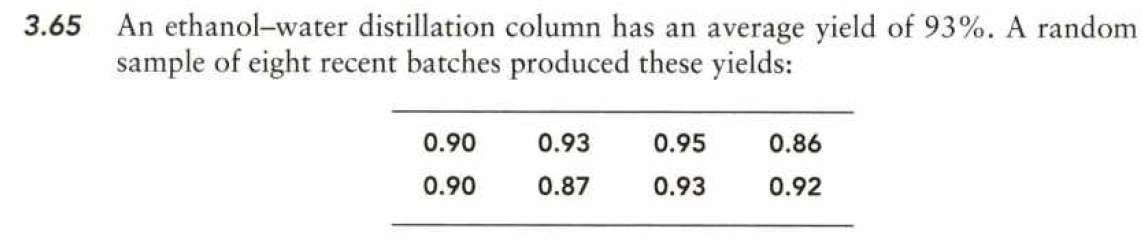

clear
data = [0.90 0.93 0.95 0.86 0.90 0.87 0.93 0.92]

data =     0.9000    0.9300    0.9500    0.8600    0.9000    0.8700    0.9300    0.9200


### a)

Find the sample mean for these data.

y_bar = mean(data)

y_bar = 0.9075

### b)

Assume that the historical average is true. Calculate the observed value of the t-statistic. Use the rough rules of thumb to interpret your result.

true_mu = 0.93;
n = length(data);
df = n - 1; %degrees of freedom
data_op = data.^2;
ss = (n * sum(data_op) - sum(data)^2)/(n*df)

ss = 9.6429e-04


t = (y_bar - true_mu)/(sqrt(ss)/sqrt(n))

t = -2.0494

Med hjemme lavede funktion

s = STAT.stik_standard_afvigelse(data)

s = 0.0311

% t = (y_bar - true_mu)/(s/sqrt(n))
t = STAT.t_student(data,s,true_mu)

t = -2.0494

P_t = tpdf(t,df)

P_t = 0.0587

Da vi få en t-værdi på -2,05 virker det usandsynligt men ikke meget usandsynligt at vores stik prøve er repressentativ.

### c)

What did you assume to do the informal analysis? Can you evaluate how well these data meet the assumptions? If yes, determine how comfortable you are with them. If not, explain why.

Vi antog at vi kendte den sande middelværdi af populationen og at den var normal fordelt.

Da vi får en t værdi på -2,05 er jeg ikke helt komfortable med tallet samt at variansen ikke kendes.

well-behaved pop.(distribution); stem-leaf/normal prob, plot

stemleafplot(data,-2)

  8 | 6 7
  9 | 0 0 2 3 3 5
key: 36|5 = 3.65
stem unit: 0.10
leaf unit: 0.01


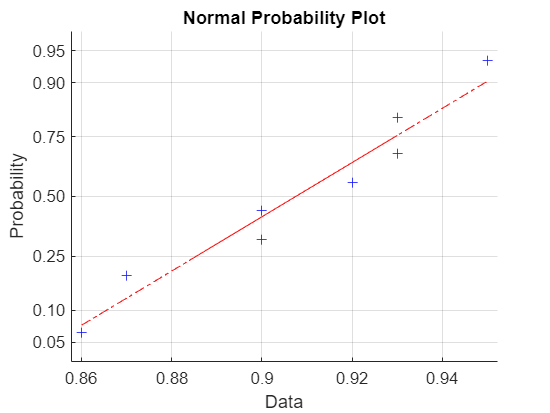

normplot(data)

Dog ses det at dataen ligger fint fordelt på normal plottet hvilket tyder på en okay stik prøve.

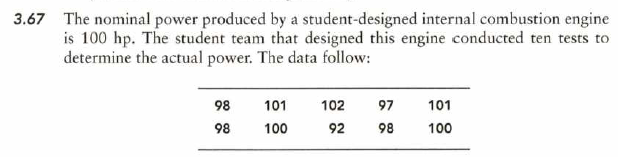

### a)

Find the sample mean, the sample variance, and the sample standard deviation for these data.

clear
data = [98 101 102 97 101 98 100 92 98 100];
y_bar = mean(data)

y_bar = 98.7000

[s, ss] = STAT.stik_standard_afvigelse(data)

s = 2.8694

ss = 8.2333

true_mu = 100

true_mu = 100

Middel værdien af stikprøven er således **98,7hp**

sample variance findes til **8,2**

sample standard deviation findes til **2,9** 

### b)

Assume that the nominal average is true. Calculate the observed value for the t-statistic. Use the rough rules of thumb to interpret your result.


t = STAT.t_student(data, s, true_mu)

t = -1.4327

Efter som |t| er 1,43 så kan vi stole på at stik prøven er korrekt inden for en rimelig sandsynlighed

### c)

What did you assume to do this analysis? How comfortable are you with these assumptions?

Vi antog at vores population er normal fordelt omkring 100hp

stemleafplot(data,0)

  9 | 2 7 8 8 8
 10 | 0 0 1 1 2
key: 36|5 = 365
stem unit: 10
leaf unit: 1


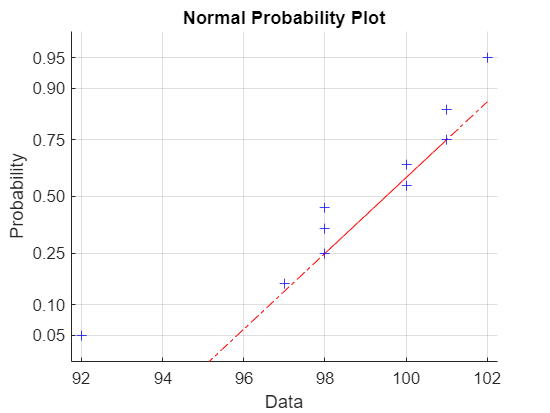

normplot(data)

Når vi ser på vores stem and leaf og normal plot ses det at der er en fin fordeling med en enkelt afstikker.

help STAT.stik_standard_afvigelse

  Udregner stik varians (s) med data som input 
  Kald: [s, ss] = stik_standard_afvigelse(data)
  Input:
    data = dataen
  Output:
    s = stikprøve standard afvigelsen    
    ss = stikprøve variansen

